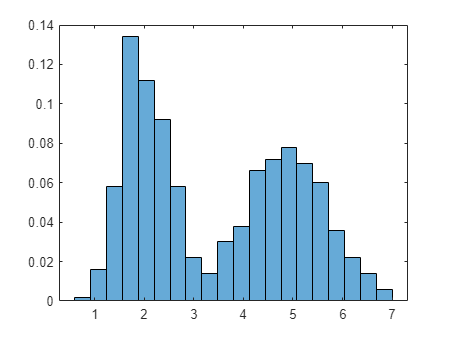

h =   Histogram with properties:

             Data: [500×1 double]
           Values: [0.0020 0.0160 0.0580 0.1340 0.1120 0.0920 0.0580 0.0220 0.0140 0.0300 0.0380 0.0660 0.0720 0.0780 0.0700 0.0600 0.0360 0.0220 0.0140 0.0060]
          NumBins: 20
         BinEdges: [0.6000 0.9200 1.2400 1.5600 1.8800 2.2000 2.5200 2.8400 3.1600 3.4800 3.8000 4.1200 4.4400 4.7600 5.0800 5.4000 5.7200 6.0400 6.3600 6.6800 7]
         BinWidth: 0.3200
        BinLimits: [0.6000 7]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


%% MXB261 - Modelling and Simulation Science Assignment 1
% Part 2 - Sampling from Experimental Data - 5 marks

Data0 = readmatrix('sample2022.txt');
figure
h = histogram(Data0, 20, 'Normalization','probability') %Change the bin size here

% Creating cumulative_prob table which calculates the cumulative
% probabiltiy of the dataset
for i = 1: h.NumBins
    probabilities(i,1) = h.Values(i)/sum(h.Values);
end

cumulative_prob = cumsum(probabilities);


d_ranges = zeros(length(h.BinEdges),1);

for i = 1: length(h.BinEdges)
    d_ranges(i,1) = h.BinEdges(i);
end
cumulative_prob = [d_ranges [0;cumulative_prob]];

%% Calculating the Sample Data
N = 500; %no of samples
rng(1);

for i = 1:N
    u = rand; %sampling a random value U(0,1)
    for j = 2:h.NumBins +1
        if u <= cumulative_prob(j,2) %index the next value of a row vector and determine if that indexed value is less than the random value from uniform distribution.
            x1 = cumulative_prob(j-1,1); % set x1 = left RV
            x2 = cumulative_prob(j,1); % set x2 = right RV
            y1 =  cumulative_prob(j-1,2); % set y1 = left CDF value
            y2 = cumulative_prob(j,2); %set y2 = right CDF value
            
            break
        end
    end
    sample_CDF_continuous(i) = (u-y1)*(x2-x1)/(y2-y1)+x1;
   sample_CDF_continuous;
end

DataNew = sample_CDF_continuous;


%Plotting the sampled values vs the experiment data
figure
sgtitle('Probability Distribution Bins = 20')
subplot(1,2,1)
h2 = histogram(Data0,20,'Normalization','pdf')

h2 =   Histogram with properties:

             Data: [2.6952 2.5523 1.2661 1.7372 1.6541 2.2881 1.7590 1.8903 2.7197 2.0569 1.6962 2.6424 2.2089 3.5944 2.7736 2.1665 1.5931 2.2462 2.1874 1.6376 3.2368 2.4051 1.8462 2.4292 2.1203 2.2570 1.8424 1.7181 2.8334 1.8417 1.8962 1.2747 1.9470 … ]
           Values: [0.0062 0.0500 0.1813 0.4187 0.3500 0.2875 0.1812 0.0688 0.0438 0.0937 0.1188 0.2063 0.2250 0.2437 0.2187 0.1875 0.1125 0.0688 0.0437 0.0187]
          NumBins: 20
         BinEdges: [0.6000 0.9200 1.2400 1.5600 1.8800 2.2000 2.5200 2.8400 3.1600 3.4800 3.8000 4.1200 4.4400 4.7600 5.0800 5.4000 5.7200 6.0400 6.3600 6.6800 7]
         BinWidth: 0.3200
        BinLimits: [0.6000 7]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

set(h2,'FaceColor','r')
title('Experimental Data')
xlabel('Time to division d')
ylabel('Frequence in N samples')
xlim([0 8])


subplot(1,2,2)
h3 = histogram(DataNew,20,'Normalization','pdf')

h3 =   Histogram with properties:

             Data: [2.5367 4.7859 0.6183 2.1438 1.7290 1.5990 1.8233 2.2820 2.4601 3.8069 2.5487 4.6321 1.8668 5.4860 1.2918 4.5665 2.5382 3.9742 1.7138 1.8516 5.1200 6.1893 2.1755 4.6637 5.4767 5.5739 1.5816 1.3562 1.7841 5.4861 1.6134 2.5592 6.0390 … ]
           Values: [0.0125 0.0562 0.2188 0.3875 0.3250 0.2250 0.1875 0.0500 0.0125 0.1000 0.1625 0.2500 0.1875 0.2187 0.2437 0.2375 0.1250 0.0688 0.0500 0.0062]
          NumBins: 20
         BinEdges: [0.6000 0.9200 1.2400 1.5600 1.8800 2.2000 2.5200 2.8400 3.1600 3.4800 3.8000 4.1200 4.4400 4.7600 5.0800 5.4000 5.7200 6.0400 6.3600 6.6800 7]
         BinWidth: 0.3200
        BinLimits: [0.6000 7]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

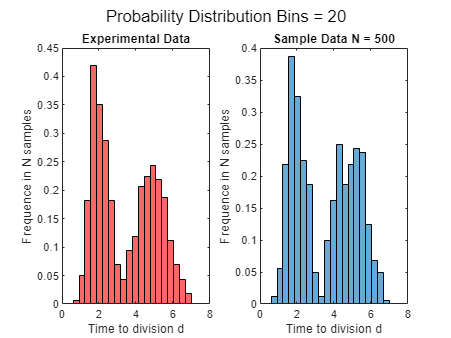

set(h3, 'FaceColor','auto')
title('Sample Data N = 500')
xlabel('Time to division d')
ylabel('Frequence in N samples')

xlim([0 8])

%% Calculating DKL
Data0 = transpose(Data0)

Data0 =     2.6952    2.5523    1.2661    1.7372    1.6541    2.2881    1.7590    1.8903    2.7197    2.0569    1.6962    2.6424    2.2089    3.5944    2.7736    2.1665    1.5931    2.2462    2.1874    1.6376    3.2368    2.4051    1.8462    2.4292    2.1203    2.2570    1.8424    1.7181    2.8334    1.8417    1.8962    1.2747    1.9470    1.8449    1.6957    1.8919    2.1902    2.2458    2.6212    1.8257    2.2123    2.3021    1.1406    1.7354    1.6224    2.0946    1.8942    1.8280    2.4434    1.8768


DKL_0toNew = sum(Data0.*(log(Data0./DataNew)))

DKL_0toNew = 360.0191


DKL2_Newto0 = sum(DataNew.*(log(DataNew./Data0)))

DKL2_Newto0 = 427.7751